# Examen 2018 Enero

#### **Cuestiones**

**1.- Mencionar dos tipos de filtros espaciales lineales paso-bajo, dos tipos de filtros espacialides paso-alto y un tipo de filtro espacial no lineal**

Filtros espaciales lineales paso-bajo

- promedio

- gausiano

Filtros espaciales lineales paso-alto

- operador laplaciano

- HighBoost

Filtros no lineales

- Gradiente (sobel o Prewitt)

- Mediana

- Máximo y mínimo

**Sea E una imagen cuyos píxeles tienen todos el mismo nivel de gris E0, y sea W la máscara 3x3 de un filtro espacial no lineal paso-alto, ¿cuál es la imagen resultante de aplicar a E el filtro espacial definido por W (dejando los bordes a 0)? En base a ello, razonar cuanto vale la suma de todos los elementos de la máscara W**

La suma de todos los elementos del filtro W y el color del pixel central. La imagen resultante será los coeficientes de la imagen original (Z0) multiplicados por el valor del pixel central de W

Dependiendo del valor de Z0, al multiplicar por W (dependerá también el valor del coeficiente central), podremos aclarar la imagen u oscurecer la imagen

**2.- Escribir un código en Matlab que transforme una imagen en color E (RGB), en una imagen en escala de grises con la misma intensidad que la imagen en color**

clear all; clc;
Imagen = imread('Scratch.png');
imshow(Imagen)

Estos son los valores para el nivel de gris K = [0.4 0.6 0.2]

k = [0.3989 0.5890 0.1540];
Imagen = Imagen(:,:,1)*k(1)+Imagen(:,:,2)*k(2)+Imagen(:,:,3)*k(3);
figure;
imshow(Imagen);

**3.- Una imagen contiene 100 pixeles codificados con 4 bits cuyo histograma es h = [0 0 0 0 0 0 2 5 7 11 55 12 8 0 0 0]. Se desea maximizar el contraste de la imagen considerando que el valor de gris 10 debe permanecer inalterado. Calcular y representar gráficamente el histograma de la imagen mejorada**

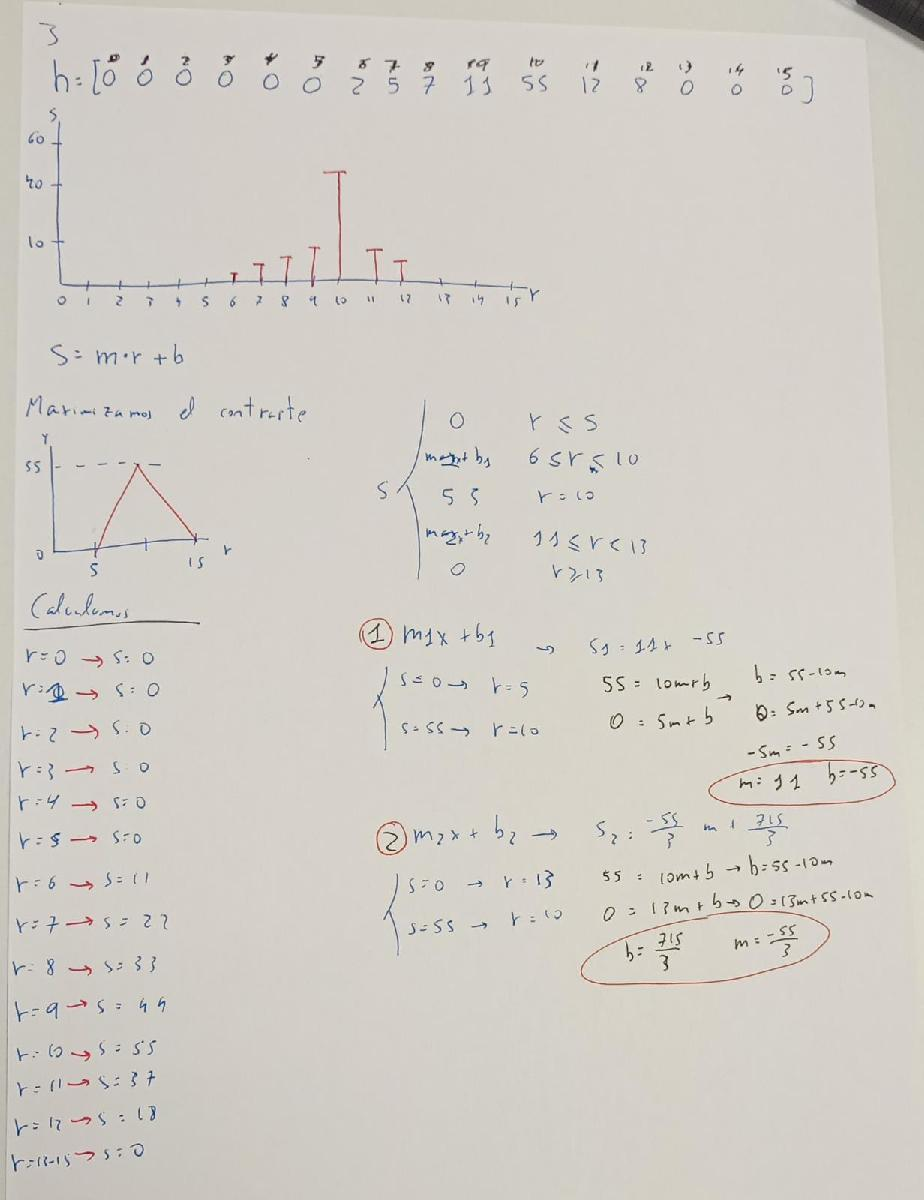

**4.- Programe una función de compresión de imágenes con predictor de primer orden que siempre proporciona una ganancia de cuatro (G = 4) con la mayor calidad posible independientemente de la imagen de entrada**

Imagen = 'Scratch.png';
G = 4;
k = 0.5;

Imagen = double(Imagen);
[N,M] = size(Imagen);

Error de predicción cuantificado

Epc = zeros(N,M);

Predictor del compresor

Pc = zeros(N,M);

Psesudoimagen (Epc + Pc) 

Pseu = zeros(N,M);

Error de predicción sin cuantificar

Epsc = zeros(M,N);

a = 2^(8/G);

efv = linspace(-k,k,G);
Epsc(:,1) = Imagen(:,1) - Pc(:,1);

for i=1:N
    v1 = Epsc(:,1);

    [N, p] = min(abs(efv)-v1);

end

**Problemas**

**1.- Dada una imagen E en escala de grises de tamaño 256x256, denotamos por Ef la transformada discreta de Fourier (DFT) de E desplazaad en frecuencia, de forma que la frecuencia (0,0) se sitúa en el píxel (129, 129) de Ef. La imagen E está contaminada con dos señales de ruido sinusoidales, que en el cuadrante superior izquierdo de Ef se observan como picos de ruido de píxeles (69, 69) y (72, 77)**

**a) Se desea filtrar la imagen E mediante un filtro paso bajo ideal con un radio D0 que sea un número entero ¿Cuál debe ser el valor entero de D0 para que dicho filtro elimine por completo el ruido y restaure la imagen lo mejor posible?**

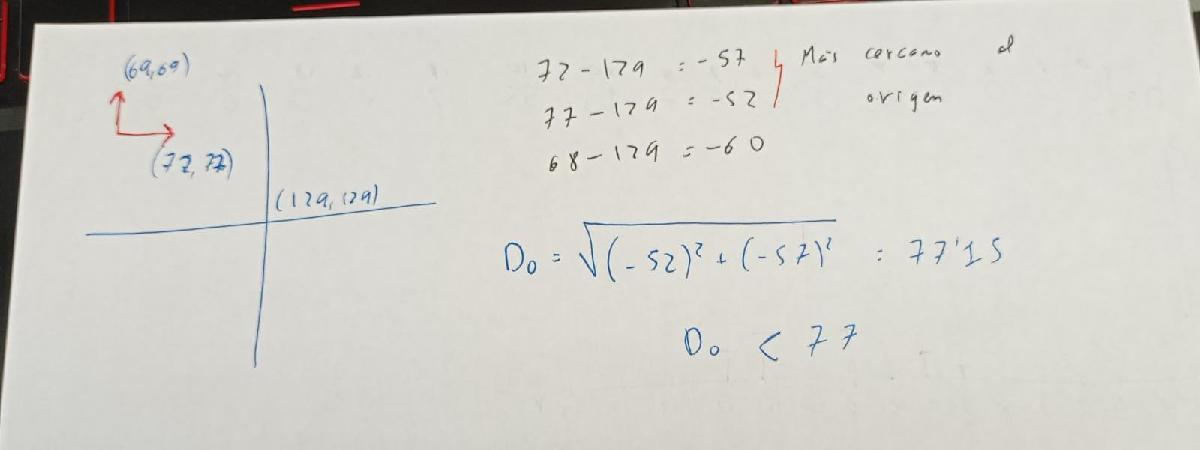

**b) Si el filtro del apartado anterior se sustituye por un filtro paso bajo Butterworth de orden n=2 y con el mismo radio entero D0, ¿que atenuaciones experimentarán cada una de las dos señales sinusoidales de ruido de la imagen?**

El filtro Butterworth se difumina cunado se aleja del centro, por lo tanto presentará una mayor atenuación el punto más cercano (72,77) y persentará una menor atenuación el más alejado (69,69)

**c) Supoganmos ahora que en vez de utilizar los filtros de los apartados a) y b) utilizamos un filtro espacial lineal de promediado con máscara de tamaño 3x3, y sea Em la imagen resultante de aplicar dicho filtro de promediado a la imagen E. Escribir la expresión de Em(i,j) en el pixel (i,j) tal que 2<= i <=255 y 2<= j <= 255, es decir (i,j), no está en el borde de la imagen**

Imagen = imread('Scratch.png');
Imagen = double(Imagen);

Obtenemos el tamaño de la imagen

[N,M] = size(Imagen);

generamos una matriz de unos 3x3 y calculamos su novena parte. lo que sería h = 1/9, lo que multiplica a cada punto de la imagen

h = [1 1 1; 1 1 1; 1 1 1]; h = h/9;

Generamos el bucle con el cuál calcularemos el filtro

for i = 2:N-1
    for j = 2:M-1
        pix = Imagen(i-1:i+1,j-1:j+1);
        Imagen(i,j) = sum(sum(pix.*h));
    end
end
Imagen = uint8(Imagen);

**d) Implementar un código en Matlab que proporcione la función de transferenica H(u,v) de un filtro de banda eliminada ideal con el fin de restaurar la imagen E eliminando por completo el ruido**

Generamos el filtro

M = 256;
N = 256;
D0 = 77;
Ancho = 3;
radio = 1;

H = ones(M,N);
for i=1:M
    for j=1:N

Le restamos 1 porque en Matlab siempre empezamos en el valor 1

        D= sqrt((i-(M/2)-1)^2 + (j-(N/2)-1)^2);
        if D<= radio+Ancho/2 && D>= radio-Ancho/2
            H(i,j) =0;
        end
    end
end

**2.- Empleando cámaras de visión artificial en proyecto de coches autónomos, se desea extraer información de la carretera y de los peatones que cruzan**

**a) Con objeto de identificar el perfil de una carretera, se ha pasado a la imagen una máscara de gradiente y posteriormente se ha binarizado dicha imagen. Se desea extraer las 2 líneas principales de la imagen binarizada mediante la *****transformada de Hough. *****Para ello, programe una función que devuelva la tabla de acumulación de Hough**

**H = TransformadaHough(imagenbinaria)**

ImagenBinaria = imread('Scratch.png');
[N,M] = size(ImagenBinaria);
ms = linspace(-1, 1, 100);
bs = linspace(-2*N, 2*N, 100);
H = zeros(N,M);

for i = 1:N
    for j = 1:M

        if ImagenBinaria(i,j)
            for k=1:ms
                b = j-(ms(k)*i);
                Diferencia = bs -b;
                [min1, p1] = min(abs(Diferencia));
                Diferencia(p1) = 1000;
                H(k,p1) = H(k,p1)+1;
                H(k, p2) = H(k, p2) +1;

            end
        end

    end
end

**b) También se desea detectar peatones que puedan estar cruzando la carretera con objeto de activar el sistema de frenado de seguridad. Describa con el mayor detalle posible el método de detección de peatones más adecuado actualmente utilizando tratamiento digital de imágenes**

Algoritmo de doufer-penker